# ความน่าจะเป็นและสัญญาณสุ่ม (Probability & Random Signal)

# ตอนที่ 8 : สัญญาณสุ่ม (Random Signal)

เราได้ศึกษาเกี่ยวกับสัญญาณซึ่งเป็นค่าที่แปรเปลี่ยนไปตามเวลา(หรือปริภูมิ) ซึ่งเราจะกำหนดให้ตัวแปร $t$ เป็นตัวแปรอิสระที่บ่งบอกถึงเวลา **หากสัญญาณนั้นมีความไม่แน่อน เราจะเรียกสัญญาณดังกล่าว่า สัญญาณสุ่ม (random signal)**

**หากเรามองในมุมองของสัญญาณที่เกิดจากการทดลอง สัญญาณสุ่มคือสัญญาณที่ไม่เหมือนเดิมเมื่อทำการทดลองซ้ำ **

## การจำลองข้อมูลการสุ่มของสัญญาณสุ่ม

กำหนดให้เราสังเคราะห์ข้อมูลเสมือนของสัญญาณสุ่มขึ้นมา

โดยที่สัญญาณสุ่มจะมีทั้งหมด $n$ ช่อง/ตัว 


$$\mathbf{X}\left\lbrack k\right\rbrack :\mathbf{Z}\to \Re^n$$


และแต่ละช่องจะถูกเก็บค่าในช่วงเวลาทั้งหมด $N$ ค่า (โดยสุ่มตัวอย่าง หรือ sample) 


$$\bar{\mathbf{X}} =\left\lbrack \begin{array}{ccc}
\mathbf{X}\left\lbrack 1\right\rbrack  & \cdots  & \mathbf{X}\left\lbrack N\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
X_1 \left\lbrack 1\right\rbrack  & \cdots  & X_1 \left\lbrack N\right\rbrack \\
\vdots  & \ddots  & \vdots \\
X_n \left\lbrack 1\right\rbrack  & \cdots  & X_n \left\lbrack N\right\rbrack 
\end{array}\right\rbrack$$


และเราเก็บค่าทั้งหมด $M$ รอบ

**เราสามารถเก็บข้อมูลดังกล่าวในรูปของ array หลายมิติได้ โดยที่เราจะกำหนดให้ มิติที่หนึ่งคือเวลา (**$1\;\mathrm{ถึง}\;N$**) มิติที่สองคือตัวแปร (**$1\;\mathrm{ถึง}\;n$**) และมิติที่สามคือครั้งในการเก็บข้อมูล (**$1\;\mathrm{ถึง}\;M$**)**  ซึ่งเราเขียนเป็น pseudo-code คร่าวๆได้ดังนี้

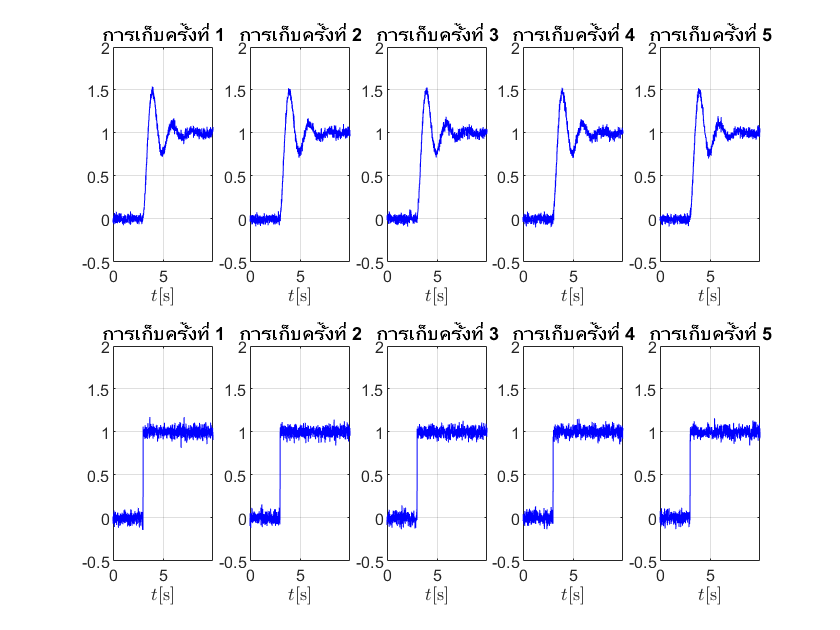

% การจำลองข้อมูล (ไม่ใช่ข้อมูลจริง)
N = 1000;
f_s = 100;
f = 0.5;
w = 2*pi*f;
dt = 1/f_s;
t = (0:dt:dt*(N-1));
y_1 = (1-exp(-0.75*(t-3)).*cos(w*(t-3))).*(t>3);
y_2 = (t>3);
n = 2;
M = 5;
dataset = zeros(N,n,M);
var = [0.001;0.002];
covar = 2*sqrt(abs(prod(var)))*(rand-1/2);
P_sim = diag(var)+[0 covar; covar 0];
for k = 1:M
    dataset(:,:,k) = [y_1' y_2']+mvnrnd([0;0],P_sim,N);
end


clf
for j = 1:n
    for k = 1:M
        ax = subplot(n,M,M*(j-1)+k);
        plot(ax,t,dataset(:,j,k),'b')
        axis(ax,[min(t) max(t) -0.5 2])
        grid(ax,'on')
        xlabel('$t$[s]','Interpreter',"latex")
        title(ax,sprintf('การเก็บครั้งที่ %d',k))
    end
end

## ค่าเฉลี่ย

**เมื่อเราทดลองและเก็บผลหลายครั้ง เราต้องมั่นใจว่าการทดลองแต่ละครั้งนั้นถูกควบคุมให้เงื่อนไขต่างๆเป็นเหมือนกัน** ผลลัพธ์ที่ได้มานั้นจะมีความแปรปรวนในแต่ละรอบการทดลอง **เราสามารถหาค่าเฉลี่ยของการทดลองได้โดยการนำผลของการทดลองแต่ละครั้งมาหารเฉลี่ยกัน แต่เราจะไม่นำค่าในช่วงเวลามาหารเฉลี่ยกัน หรือกล่าวอีกอย่างคือ เราจะไม่นำค่าที่มีเวลาเป็นคนละเวลามาหารเฉลี่ยรวมกัน** 


$$\mu_{\mathbf{X}} \left\lbrack k\right\rbrack =E\left\lbrace \mathit{\mathbf{X}}\left\lbrack k\right\rbrack \right\rbrace =\frac{1}{M}\sum_{j=1}^M \left\lbrace {\mathit{\mathbf{X}}}^{\left(j\right)} \left\lbrack k\right\rbrack \right\rbrace$$


โดยที่ ${\mathit{\mathbf{X}}}^{\left(j\right)} \left\lbrack k\right\rbrack$ คือค่าของตัวแปรสุ่มทุกตัว ณ การทดลองที่ $j$ และเวลาที่ $k$

เราสามารถใช้ฟังก์ชัน mean ในการหาค่าเฉลี่ยโดยที่เราจะเฉลี่ยข้อมูลในมิติที่สาม เราสามารถคำนวณและกราฟค่าเฉลี่ยและข้อมูลได้ดังต่อไปนี้

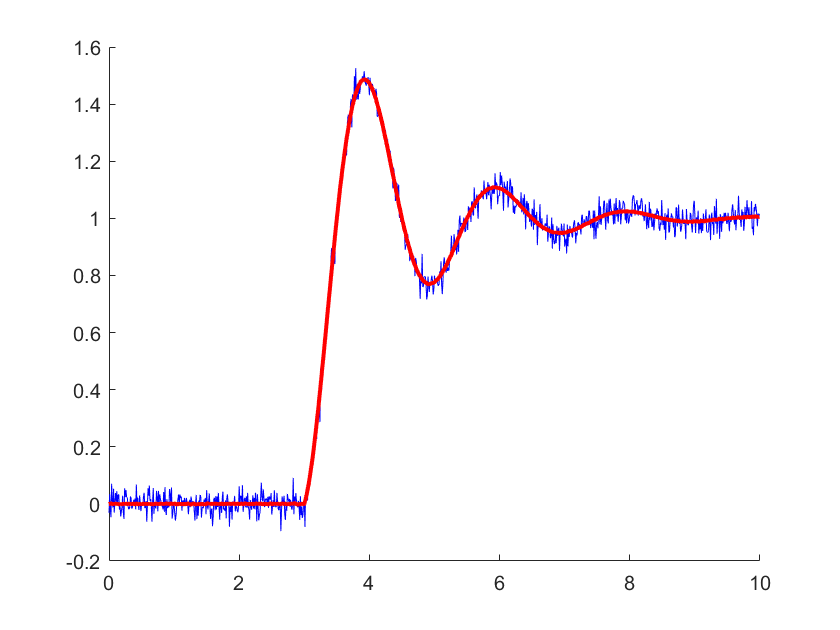

N = 1000;
f_s = 100;
f = 0.5;
w = 2*pi*f;
dt = 1/f_s;
t = (0:dt:dt*(N-1));
y_1 = (1-exp(-0.75*(t-3)).*cos(w*(t-3))).*(t>3);
y_2 = (t>3);
n = 2;
M = 1000;
dataset = zeros(N,n,M);
var = [0.001;0.002];
covar = 2*sqrt(abs(prod(var)))*(rand-1/2);
P_sim = diag(var)+[0 covar; covar 0];
for k = 1:M
    dataset(:,:,k) = [y_1' y_2']+mvnrnd([0;0],P_sim,N);
end
mu = mean(dataset,3);
clf;
ax = axes;
hold(ax,'on')
plot(ax,t,dataset(:,1,1),'b')
plot(ax,t,mu(:,1),'r','LineWidth',2)

## เมตริกซ์ค่าแปรปรวนร่วมเกี่ยว

เช่นเดียวกับการหาค่าเฉลี่ย **เราสามารถคำนวณหาเมตริกซ์ค่าแปรปรวนร่วมเกี่ยวของสัญญาณได้ โดยคำนวณหาเมตริกซ์ในแต่ละเวลา **$k$ ผลที่ได้คือเมตริกซ์ ${\mathbf{K}}_{\mathbf{X}} \left\lbrack k\right\rbrack$ ทั้งหมด $N$ ตัว 


$${\mathbf{K}}_{\mathbf{X}} \left\lbrack k\right\rbrack =\mathrm{Cov}\left\lbrace \mathit{\mathbf{X}}\left\lbrack k\right\rbrack ,\mathit{\mathbf{X}}\left\lbrack k\right\rbrack \right\rbrace$$


**หากในทุกเวลา **$k$** เมตริกซ์แต่ละตัวมีค่าที่ใกล้เคียงกัน เราสามารถประมาณได้ว่าคุณลักษณะทางสถิติของทั้งสัญญาณนั้นไม่แปรเปลี่ยน หรือเรียกอีกอย่างได้ว่า สัญญาณนั้นเป็นสัญญาณนิ่ง (stationary signal)**

เราสามารถประมาณได้ว่าเมตริกซ์ค่าแปรปรวนร่วมเกี่ยวได้ดังต่อไปนี้ 

 
$${\mathbf{K}}_{\mathbf{X}} \approx \frac{1}{N}\sum_{k=1}^N {\mathbf{K}}_{\mathbf{X}} \left\lbrack k\right\rbrack$$


เราสามารถเขียนโปรแกรมจำลองการทดลองได้ดังต่อไปนี้

N = 1000;
f_s = 100;
f = 0.5;
w = 2*pi*f;
dt = 1/f_s;
t = (0:dt:dt*(N-1));
y_1 = (1-exp(-0.75*(t-3)).*cos(w*(t-3))).*(t>3);
y_2 = (t>3);
n = 2;
M = 1000;
dataset = zeros(N,n,M);
var = [0.001;0.002];
covar = 2*sqrt(abs(prod(var)))*(rand-1/2);
P_sim = diag(var)+[0 covar; covar 0];
for k = 1:M
    dataset(:,:,k) = [y_1' y_2']+mvnrnd([0;0],P_sim,N);
end
mu = mean(dataset,3);
K_XX = zeros(n);
for j = 1:N
    % for each t, compute covriance matrix
    K_XX = K_XX + cov(permute(dataset(j,:,:),[3,2,1])); 
end
K_XX = K_XX/N

K_XX =     0.0010    0.0002
    0.0002    0.0020


**เราสามารถนำเมตริกซ์ดังกล่าวเพื่ออธิบายความไม่แน่นอนของค่าที่วัดได้จากเซนเซอร์และนำไปใช้ต่อในการทำตัวกรองคาลมาน (Kalman Filter)**